# Emmanuelle Chaigneau

# Serge Charpak Lab

# Figure 3 Dual color ratiometric measurements

## Load data

### Experimental values of epsilon for total hemoglobin 

load('EpsilonHbO2Hb.mat');

LambdaHbToResamp = EpsilonHbO2Hb(:,1) ;
EpsilonHbO2ToResamp = EpsilonHbO2Hb(:,2) ;
EpsilonHbToResamp = EpsilonHbO2Hb(:,3) ;

[EpsilonHbO2Resamp, ~] = resample(EpsilonHbO2ToResamp, LambdaHbToResamp, 1) ;
[EpsilonHbResamp, LambdaHbResamp] = resample(EpsilonHbToResamp, LambdaHbToResamp, 1) ;

RangeHb = (LambdaHbResamp >= 430) & (LambdaHbResamp <= 980) ;

EpsilonHbO2 = 2.303 * EpsilonHbO2Resamp(RangeHb) ;             % cm-1 M-1
EpsilonHb = 2.303 * EpsilonHbResamp(RangeHb) ;                 % cm-1 M-1

ConcTotHbBlood = 150 / 64500 ;                      % M
              % Hb 150 ± 10 g/L in mouse blood for hematocrit 0.47 REF Raabe jaalas 2011       
              % and MW = 64500 (https://www.acs.org/molecule-of-the-week/archive/h/hemoglobin.html)
XiBlood = 0.05 ;                                  
SO2 = 0.8;                                          % Lyons elife 2016

MuABloodHbTot = ConcTotHbBlood * 0.0001 * (SO2 * EpsilonHbO2 + (1 - SO2) * EpsilonHb );


### Brain hemoglobin 

MuABrainHbTot = XiBlood * MuABloodHbTot ;


### Experimental values of epsilon for water 

load('Lambda_MuaWater.mat');
LambdaWaterToResamp = Lambda_MuaWater(:,1) ;
MuWaterToResamp = Lambda_MuaWater(:,2) ;
[MuWaterResamp, LambdaWaterResamp] = resample(MuWaterToResamp, LambdaWaterToResamp, 1) ;
BooIdxWater430to980 = logical((LambdaWaterResamp >= 430) .* (LambdaWaterResamp <= 980));
LambdaWater = LambdaWaterResamp(BooIdxWater430to980) ;
XiWater = 0.8 ;
MuABrainWater = XiWater * MuWaterResamp(BooIdxWater430to980) * 0.0001 ;    


### Experimental values of epsilon for Lipid 

load('Lambda_MuaLipid.mat');
LambdaLipid = Lambda_MuaLipid(:,1);
BooIdxLipid430 = LambdaLipid == 430;
BooIdxLipid980 = LambdaLipid == 980;
[ValIdxLipid430, IdxLipid430] = max(BooIdxLipid430);
[ValIdxLipid980, IdxLipid980] = max(BooIdxLipid980);
MuLipid = Lambda_MuaLipid(IdxLipid430:IdxLipid980,2) * 0.0001 ;           % um-1
LambdaLipid = LambdaLipid(IdxLipid430:IdxLipid980);
 
XiLipid = 0.12 ;
MuABrainLipid = XiLipid * MuLipid ;


### Summary absorption

MuABrainTot = MuABrainHbTot +  MuABrainWater + MuABrainLipid ;


## Scattering fit following Mie theory details

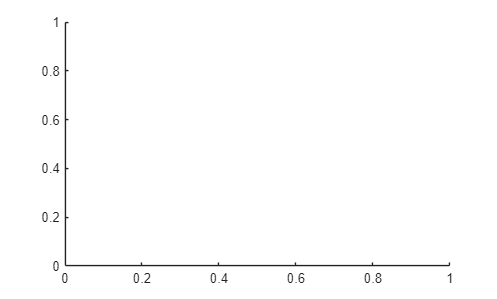

nexttile([1 1])


gs = 0.86 ;


### Experimental values of mus

load('Lambda_MusBrain.mat');
Lambda=Lambda_Mus(:,1);
Mus=Lambda_Mus(:,2);
[xData, yData] = prepareCurveData( Lambda, Mus );
LambdaFit = 430:1:980;


### Set up fittype and options.

ft = fittype( 'a*(x/500)^-b', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.0042 3];


### Fit model to data.

[fitresult, gof] = fit( xData, yData, ft, opts );
fitcoeffvals= coeffvalues(fitresult);
a = fitcoeffvals(1); 
b = fitcoeffvals(2); 
ConfMatFit = confint(fitresult,0.95);
MusFit= a * (LambdaFit / 500).^-b;
MusFitMinErr= ConfMatFit(1,1) * (LambdaFit / 500).^-ConfMatFit(2,2);
MusFitPluErr= ConfMatFit(2,1) * (LambdaFit / 500).^-ConfMatFit(1,2);


### Total absorption and reduced scattering

MusrFit = MusFit *(1 - gs);
MuBrainTr = MuABrainTot + MusrFit';
MuBrainT = MuABrainTot + MusFit';

MuBloodTr = MuABloodHbTot + MusrFit';
MuBloodT = MuABloodHbTot + MusFit';


## Ratios

RatioMuBlood = MuABloodHbTot ./ MusFit' ;
RatioMuBrain = MuABrainTot ./ MusFit' ;

RatioMuTBlood = MuBloodT ./ MuBloodTr ;
RatioMuTBrain = MuBrainT ./ MuBrainTr ;


## Parameters Figure 3

figure

Fig3TitleFontsize = 14 ;
Fig3LegendFontsize = 10 ;
Fig3AxisLabelFontsize = 12 ;
Fig3Linewidth = 2 ;

Figure3 = figure;
Figure3.Position = [10 10 900 300] ;
Figure3Layout = tiledlayout(1,2);
Figure3Layout.Padding = 'tight';

## Panel (a)

## Ratio between Mua and Mus 

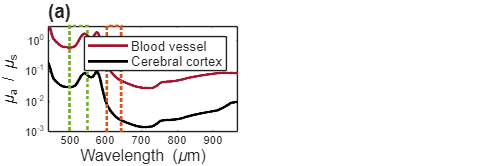

nexttile([1 1]) ;

% Plot fit with data.
hRatioBlood = semilogy( LambdaFit, RatioMuBlood, 'r') ;
hold on
hRatioBrain = semilogy( LambdaFit, RatioMuBrain, 'k') ;
hold off

legend( "Blood vessel", "Cerebral cortex", 'Location', 'northeast', 'FontSize', Fig3LegendFontsize);
xlabel('Wavelength (\mum)',"FontSize", Fig3AxisLabelFontsize) ;
ylabel( "\mu_{a} / \mu_{s}","FontSize", Fig3AxisLabelFontsize) ;
axis([440 970 10^-3 3]) ;
xticks([500 600 700 800 900 ]) ;
yticks([0.001 0.01 0.1 1]) ;

hRatioBlood.Color = [0.6350 0.0780 0.1840] ;
hRatioBlood.LineWidth = Fig3Linewidth ;
hRatioBrain.LineWidth = Fig3Linewidth ;

RectGreen = rectangle('Position', [500 5*10^-4 50 2.99], 'EdgeColor', [0.4660 0.6740 0.1880]) ;
RectRed = rectangle('Position', [604 5*10^-4 40 2.99], 'EdgeColor',[0.8500 0.3250 0.0980]) ;
RectGreen.LineWidth = Fig3Linewidth ;
RectRed.LineWidth = Fig3Linewidth ;
RectGreen.LineStyle =":" ;
RectRed.LineStyle =":" ;

title("(a)", 'FontSize', Fig3TitleFontsize)
ax = gca ;
ax.TitleHorizontalAlignment = 'left';

## Panel (b)

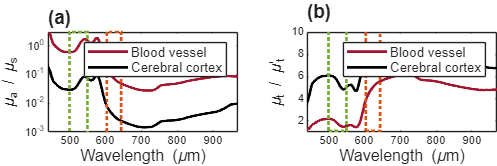

nexttile([1 1])

% Plot fit with data.
hRatioBloodT = plot( LambdaFit, RatioMuTBlood, 'r') ;
hold on
hRatioBrainT = plot( LambdaFit, RatioMuTBrain, 'k') ;
hold off

legend( "Blood vessel", "Cerebral cortex", 'Location', 'northeast', 'FontSize', Fig3LegendFontsize);
xlabel('Wavelength (\mum)',"FontSize", Fig3AxisLabelFontsize) ;
ylabel( "\mu_{t} / \mu'_{t}","FontSize", Fig3AxisLabelFontsize) ;
axis([440 970 1 10]) ;
xticks([500 600 700 800 900 ]) ;

hRatioBloodT.Color = [0.6350 0.0780 0.1840] ;
hRatioBloodT.LineWidth = Fig3Linewidth ;
hRatioBrainT.LineWidth = Fig3Linewidth ;

RectGreen = rectangle('Position', [500 1.1 50 9.9], 'EdgeColor', [0.4660 0.6740 0.1880]) ;
RectRed = rectangle('Position', [604 1.1 40 9.9], 'EdgeColor',[0.8500 0.3250 0.0980]) ;
RectGreen.LineWidth = Fig3Linewidth ;
RectRed.LineWidth = Fig3Linewidth ;
RectGreen.LineStyle =":" ;
RectRed.LineStyle =":" ;

title("(b)", 'FontSize', Fig3TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';